t = 0 : 0.01 : 2*pi

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


f = 1

f = 1

w = 2 * pi * f

w = 6.2832

L = length(t)

L = 629

s = sin(w*t)

s =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628



r = [zeros(1,L), s, zeros(1,2*L), 0.5*s, zeros(1,L)]

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M = length(s) % length of sin(w*t)

M = 629

M2 = length(zeros(1,L)) % length of zeros

M2 = 629

M3 = length(r) % total length

M3 = 3774

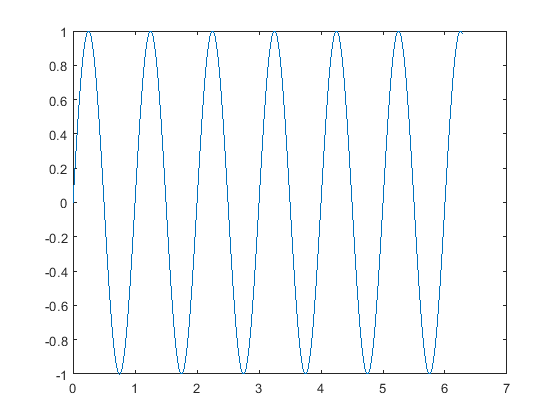


plot(t,s)

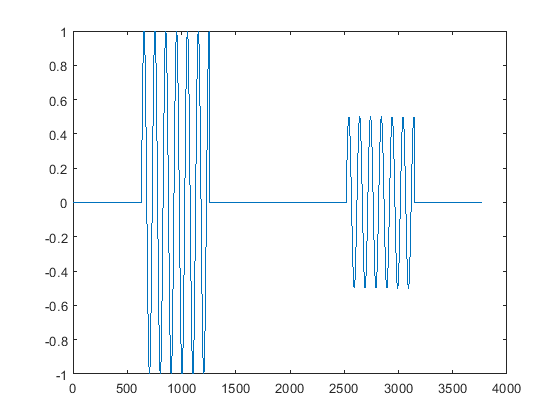

plot(r)


ct1 = length(r)-L;                       
for a = 0:ct1
    c(a+1) = r(a+1:a+L)*s';
end
M4 = length(ct1) % 3774 - 629 x

M4 = 1


[m,i] = max(r)

m = 1

i = 655

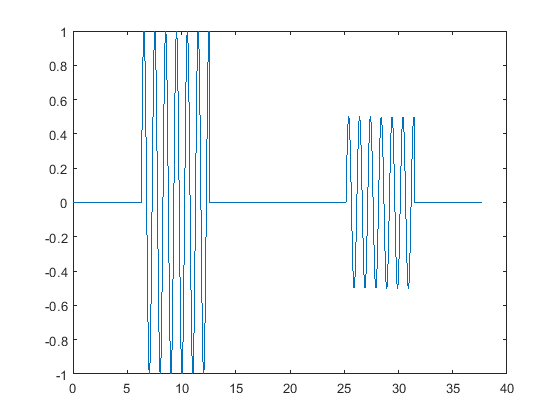

plot((0:length(r)-1)*0.01, r)

M5 = length(c) %total length of c 

M5 = 3146

[n,j] = max(c)

n = 315.9452

j = 630

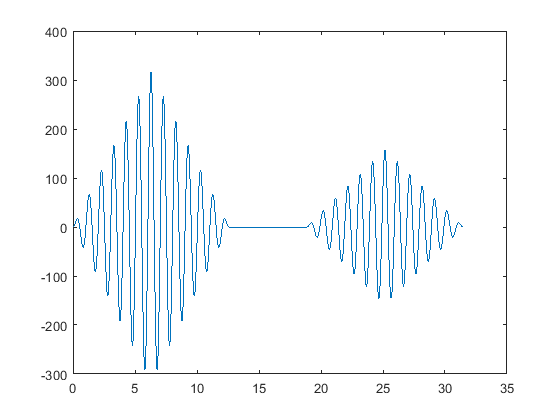

plot((0:length(c)-1)*0.01, c)


Y = [zeros(1,1500),ones(1,1646)]

Y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


c1 = min(Y,c(1,1500))

c1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[n2,j2] = max(c1)

n2 = 0

j2 = 1


% first assume %
% transmit signal sample max value = 6285
% received signal sample max value = 25000
% time difference = (25000 - 6285) * 0.01[s] = 187.15[s]
% distance = (187.15/2) * 3*10^8[m/s] = 28,072,500,000[m] ? 

% second % xlabel : 0:length(c)-1)*0.01 기준
% transmit signal sample max value = 6285 * 0.01 = 62.85
% received signal sample max value = 25000 * 0.01 = 250
% time difference = (250 - 62.85) * 0.01[s] = 1.8715[s]
% distance = (187.15/2) * 3*10^8[m/s] = 280,725,000[m] ?

%*************************************************
q1 = [zeros(1,L), s , zeros(1,L)]

q1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


q2 = [zeros(1,4*L), 0.5*s ,zeros(1,L)]

q2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q = [q1, zeros(1,L), 0.5*s, zeros(1,L) ]

Q =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



[m1,i1] = max(q1)

m1 = 1

i1 = 655

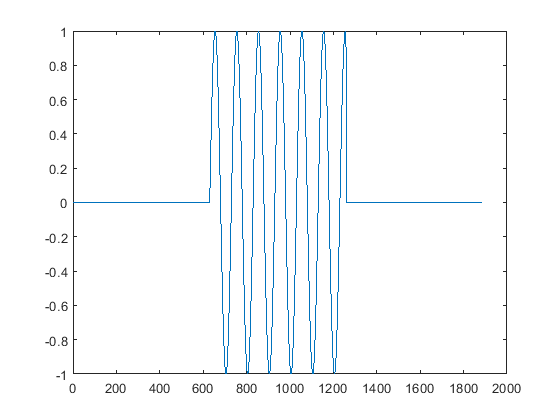

plot(q1)

[m2,i2] = max(q2)

m2 = 0.5000

i2 = 2542

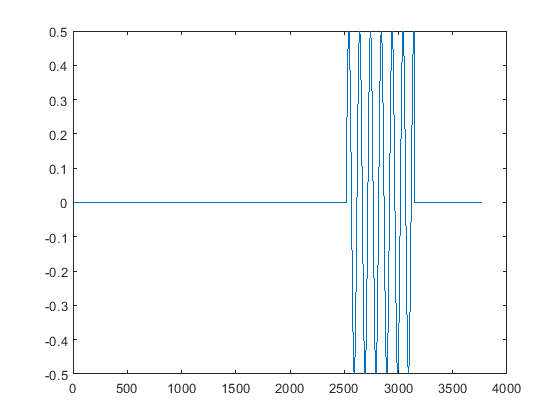

plot(q2)


plot(Q)

delta_t=(i2-i1)*0.01 % 단위 s

delta_t = 18.8700

distance = (delta_t/2)*3*10^8 % 단위 m 

distance = 2.8305e+09